clear all

a = -1; b = 1;
N = 5; n = 62;
alpha = N / 2;
beta = n - 55;
gamma = -alpha / (4 * (alpha + beta));
k = 41; h = (b - a) / (k - 1);
A = a:h:b;

syms tau real
syms phi(tau)

warning('off')
syms C [1, 5]

phi(tau) = C(1) * tau^4 + C(2) * tau^3 + C(3) * tau^2 + C(4) * tau + C(5);

eqn     =   diff(phi(tau), tau, 2) + (tau + gamma) * diff(phi(tau), tau, 1) - ...
            4 * phi(tau) == (12*alpha - 3*gamma*alpha + 14*beta)*tau^2 - ...
            (9*alpha + 2*gamma*beta)*tau - 4*alpha + gamma*alpha - 2*beta

$$eqn = 2\,C_{3}-4\,C_{5}+6\,C_{2}\,\tau -4\,C_{4}\,\tau +12\,C_{1}\,\tau^{2}-4\,C_{1}\,\tau^{4}-4\,C_{2}\,\tau^{3}-4\,C_{3}\,\tau^{2}+\left(\tau -\frac{5}{76}\right)\,\left(4\,C_{1}\,\tau^{3}+3\,C_{2}\,\tau^{2}+2\,C_{3}\,\tau +C_{4}\right)=\frac{19531\,\tau^{2}}{152}-\frac{410\,\tau }{19}-\frac{3673}{152}$$


 phi(a) == 2*alpha

$$ans = C_{1}-C_{2}+C_{3}-C_{4}+C_{5}=5$$

 phi(b) == 2*alpha

$$ans = C_{1}+C_{2}+C_{3}+C_{4}+C_{5}=5$$


cond = [12 * C(1) + 2* C(3) + 3*gamma*C(2) - 4*C(3) == 12*alpha - 3*gamma*alpha + 14*beta, 
        6*C(2) + 2 * gamma * C(3) - 3 * C(4) == -(9*alpha + 2*gamma*beta),
        2*C(3)+gamma*C(4)-4*C(5) == - 4*alpha + gamma*alpha - 2*beta,
        4*C(1)*gamma-C(2) == 0,
        phi(a) == 2*alpha,
        phi(b) == 2*alpha];

cond

$$cond = \left(\begin{array}{c} 12\,C_{1}-\frac{15\,C_{2}}{76}-2\,C_{3}=\frac{19531}{152}\\ 6\,C_{2}-\frac{5\,C_{3}}{38}-3\,C_{4}=-\frac{410}{19}\\ 2\,C_{3}-\frac{5\,C_{4}}{76}-4\,C_{5}=-\frac{3673}{152}\\ -\frac{5\,C_{1}}{19}-C_{2}=0\\ C_{1}-C_{2}+C_{3}-C_{4}+C_{5}=5\\ C_{1}+C_{2}+C_{3}+C_{4}+C_{5}=5 \end{array}\right)$$


[C(1), C(2), C(3), C(4), C(5)] = solve(cond, [C(1), C(2), C(3), C(4), C(5)]);

C

$$C = \left(\begin{array}{ccccc} \frac{19}{2} & -\frac{5}{2} & -7 & \frac{5}{2} & \frac{5}{2} \end{array}\right)$$


phi(tau) = C(1) * tau^4 + C(2) * tau^3 + C(3) * tau^2 + C(4) * tau + C(5)

$$phi(tau) = \frac{19\,\tau^{4}}{2}-\frac{5\,\tau^{3}}{2}-7\,\tau^{2}+\frac{5\,\tau }{2}+\frac{5}{2}$$


% simplify(diff(phi(tau), tau, 2) + (tau + gamma) * diff(phi(tau), tau, 1) - ...
%             4 * phi(tau) - ((12*alpha - 3*gamma*alpha + 14*beta)*tau^2 - ...
%             (9*alpha + 2*gamma*beta)*tau - 4*alpha + gamma*alpha - 2*beta))

% Численное решение
p(tau)  = tau + gamma;
q(tau)  = 4 * tau^0;
nu(tau) = (12*alpha - 3*gamma*alpha + 14*beta)*tau^2 - (9*alpha + 2*gamma*beta)*tau - 4*alpha + gamma*alpha - 2*beta;

P       = transpose(p(A));
Q       = transpose(q(A));


Upsilon         = transpose(nu(A));
Upsilon(1)      = 2*alpha;
Upsilon(k)  = 2*alpha;

H = zeros(k);

H(1, 1)         = 1;
for i = 2:k-1
    H(i, i - 1)     = (1/h^2 - P(i)/(2*h));
    H(i, i)         = (-2/h^2 - Q(i));
    H(i, i + 1)     = (1/h^2 + P(i)/(2*h));
end
H(k, k) = 1;

L = zeros(k, 1);
M = zeros(k, 1);

L(1) = -H(1, 2)/H(1, 1);
M(1) = Upsilon(1)/H(1, 1);
for i = 2:k-1
    L(i) = -H(i, i + 1)/(L(i-1) * H(i, i - 1) + H(i, i));
    M(i) = (Upsilon(i) - M(i-1) * H(i, i - 1))/(L(i - 1) * H(i, i - 1) + H(i, i));
end
L(k) = 0;
M(k) = (Upsilon(k) - M(k-1) * H(k, k - 1))/(L(k - 1) * H(k, k - 1) + H(k, k));

Phi = zeros(k, 1);
Phi(k) = M(k);
for i = fliplr(1:k-1)
   Phi(i) = L(i) * Phi(i + 1) + M(i); 
end

Phi;
% Phi = double(H\Upsilon)

writematrix(double(Upsilon), "D:\Материалы для обучения\МГТУ\ЛБ_ОСМ\ЛБ_ОСМ№1.xlsx", 'Sheet', 1);
writematrix(H, "D:\Материалы для обучения\МГТУ\ЛБ_ОСМ\ЛБ_ОСМ№1.xlsx", 'Sheet', 2);
writematrix(transpose(L), "D:\Материалы для обучения\МГТУ\ЛБ_ОСМ\ЛБ_ОСМ№1.xlsx", 'Sheet', 3);
writematrix(transpose(M), "D:\Материалы для обучения\МГТУ\ЛБ_ОСМ\ЛБ_ОСМ№1.xlsx", 'Sheet', 4);
writematrix(Phi, "D:\Материалы для обучения\МГТУ\ЛБ_ОСМ\ЛБ_ОСМ№1.xlsx", 'Sheet', 5);

% Правило Рунге
h_r = h / 2;
A_r = a:h_r:b;

P_r       = transpose(p(A_r));
Q_r      = transpose(q(A_r));


Upsilon_r               = transpose(nu(A_r));
Upsilon_r(1)            = 2*alpha;
Upsilon_r(2 * k - 1)    = 2*alpha;

H_r = zeros(2 * k - 1);

H_r(1, 1)             = 1;
for i = 2:2 * k - 2
    H_r(i, i - 1)     = (1/h_r^2 - P_r(i)/(2*h_r));
    H_r(i, i)         = (-2/h_r^2 - Q_r(i));
    H_r(i, i + 1)     = (1/h_r^2 + P_r(i)/(2*h_r));
end
H_r(2 * k - 1, 2 * k - 1) = 1;

L_r = zeros(2 * k - 1, 1);
M_r = zeros(2 * k - 1, 1);

L_r(1) = -H_r(1, 2)/H_r(1, 1);
M_r(1) = Upsilon_r(1)/H_r(1, 1);
for i = 2:2 * k - 2
    L_r(i) = -H_r(i, i + 1)/(L_r(i-1) * H_r(i, i - 1) + H_r(i, i));
    M_r(i) = (Upsilon_r(i) - M_r(i-1) * H_r(i, i - 1))/(L_r(i - 1) * H_r(i, i - 1) + H_r(i, i));
end
L_r(2 * k - 1) = 0;
M_r(2 * k - 1) = (Upsilon_r(2 * k - 1) - M_r(2 * k - 1 -1) * H_r(2 * k - 1, 2 * k - 1 - 1))/(L_r(2 * k - 1 - 1) * H_r(2 * k - 1, 2 * k - 1 - 1) + H_r(2 * k - 1, 2 * k - 1));

Phi_r = zeros(2 * k - 1, 1);
Phi_r(2 * k - 1) = M_r(2 * k - 1);
for i = fliplr(1:2 * k - 1-1)
   Phi_r(i) = L_r(i) * Phi_r(i + 1) + M_r(i); 
end

Phi_r;
% Phi_r = double(H_r\Upsilon_r)

for i = fliplr([2:2:2*k-2])
    Phi_r(i) = [];
end
Phi_r;

writematrix(double(Upsilon_r), "D:\Материалы для обучения\МГТУ\ЛБ_ОСМ\ЛБ_ОСМ№1.xlsx", 'Sheet', 6);
writematrix(H_r, "D:\Материалы для обучения\МГТУ\ЛБ_ОСМ\ЛБ_ОСМ№1.xlsx", 'Sheet', 7);
writematrix(L_r, "D:\Материалы для обучения\МГТУ\ЛБ_ОСМ\ЛБ_ОСМ№1.xlsx", 'Sheet', 8);
writematrix(M_r, "D:\Материалы для обучения\МГТУ\ЛБ_ОСМ\ЛБ_ОСМ№1.xlsx", 'Sheet', 9);
writematrix(Phi_r, "D:\Материалы для обучения\МГТУ\ЛБ_ОСМ\ЛБ_ОСМ№1.xlsx", 'Sheet', 10);
writematrix(abs(Phi - transpose(double(phi(A)))), "D:\Материалы для обучения\МГТУ\ЛБ_ОСМ\ЛБ_ОСМ№1.xlsx", 'Sheet', 11);

m = 2;
eps = max(transpose(abs(Phi - Phi_r))) / (2^(m-1) - 1)

eps = 0.0082

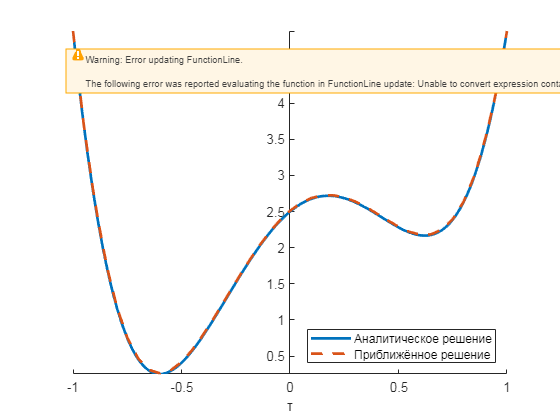


% Решение задачи интерполяции
spl(1) = piecewise((tau >= A(1)) & (tau <= A(2)), -(tau - A(2)) / (A(2) - A(1)), 0);
for i = 2:k-1
    spl(i) = piecewise((tau >= A(i - 1)) & (tau <= A(i)), (tau - A(i - 1)) / (A(i) - A(i - 1)), ...
                       (tau >= A(i)) & (tau <= A(i + 1)), -(tau - A(i + 1)) / (A(i + 1) - A(i)), 0);
end
spl(k) = piecewise((tau >= A(k-1)) & (tau <= A(k)), (tau - A(k-1)) / (A(k) - A(k - 1)), 0);

phi_appr(tau) = 0 * tau;
for i = 1:k
    phi_appr(tau) = phi_appr(tau) + spl(i) * Phi(i);
end



fplot(phi(tau), [a, b], 'Linewidth', 2)
hold on
fp = fplot(phi_appr(tau), [a, b], 'Linewidth', 2);
fp.LineStyle = '--';
legend("Аналитическое решение", "Приближённое решение");
xlabel("\tau");
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');
legend('Location', 'southeast')
box off
hold off

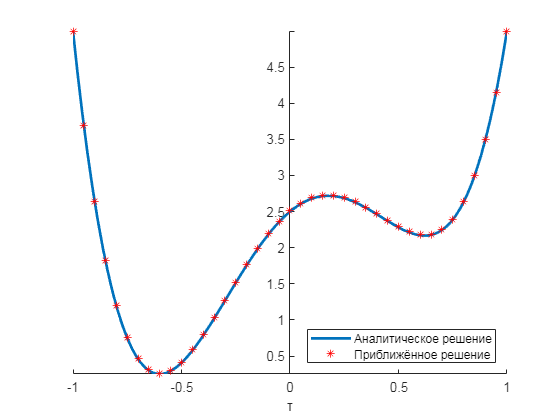


fplot(phi(tau), [a, b], 'Linewidth', 2)
hold on
fp = plot(A, Phi, 'r*');
legend("Аналитическое решение", "Приближённое решение");
xlabel("\tau");
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');
legend('Location', 'southeast')
box off
hold off